# Live Script for Developing/Testing Background Removal Algorithms.

In particular we test one based on suggestions from an email from Cheng Chin (slightly changed to use svd) and the Eigenfaces algorithm

%Add the folder with the image processing functions to the path
addpath(fullfile('.','AbsorptionImageProcessing'));

## Typical Input Images

For reference, here are some typical images from absorption imaging.  One "raw" image which inlcudes the shadow of the atoms, one "back" image which shows the beam without any atoms (the atom cloud here is small, so the difference is subtle), and one "noise" image whichis an image taken with the absorption laser off.  Note the differing color scales

%Displaying some typical input images
disp('Here are some typical input images');

Here are some typical input images


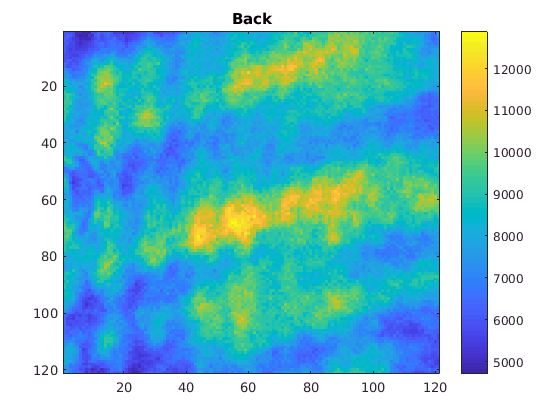


raw=load_image('20170405/Cool100d100d80PGCZ4.4_1_raw.ascii');
plot_image(raw,'Raw');

back=load_image('20170405/Cool100d100d80PGCZ4.4_1_back.ascii');
plot_image(back,'Back');

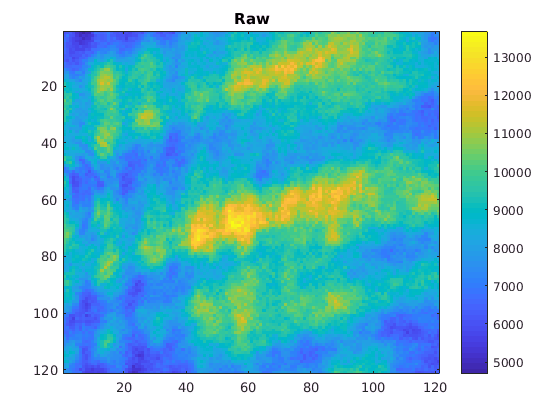


noise=load_image('20170405/Cool100d100d80PGCZ4.4_1_noise.ascii');

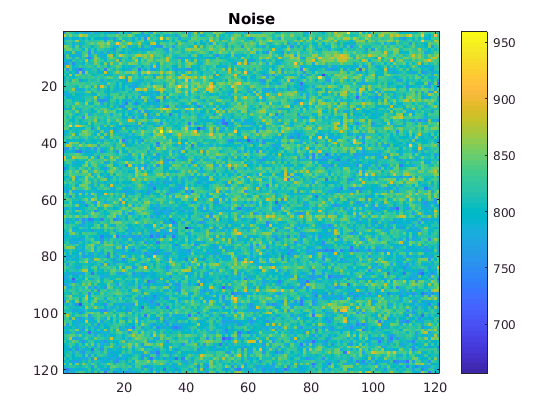

plot_image(noise,'Noise');

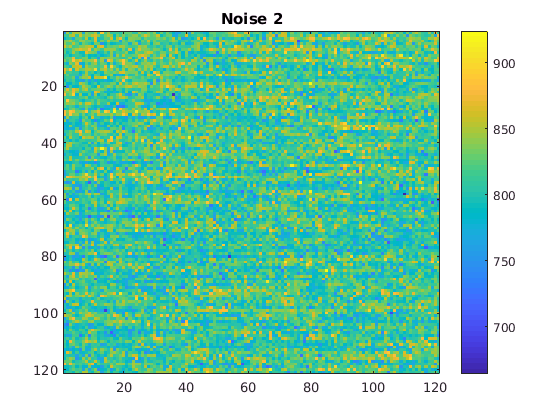


% noise2=load_image('20170405/Cool100d100d80PGCZ4.4_2_noise.ascii');
% plot_image(noise2,'Noise 2');

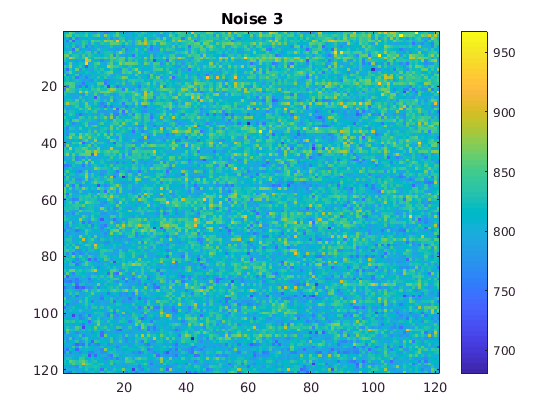

% 
% noise3=load_image('20170405/Cool100d100d80PGCZ4.4_3_noise.ascii');
% plot_image(noise3,'Noise 3');

## Typical Basis Vectors

This section shows some typical basis vectors from the svd algorithm and the eigenfaces algorithm.  Note how similar they are, and note that later basis vectors are noisier and less important.

%Now show some typical basis vectors from the svd algorithm and Eigenfaces
ls_pattern=fullfile('20170405','Savefile_4*_back.ascii'); %regex pattern to match images for basis
max_vectors=10; %Maximum number of vectors to use for basis
indices=1:10; %Number of basis vectors to plot

file_list=get_file_list(ls_pattern);
back_region=ones(size(load_image(file_list{1})));
basis_svd=make_basis_svd(file_list,back_region,max_vectors);
basis_eigen=make_basis_eig(file_list,back_region,max_vectors);
%Plot basis vectors
k_max=min(max_vectors,length(indices));
disp('Algorithm from svd basis');

Algorithm from Cheng basis


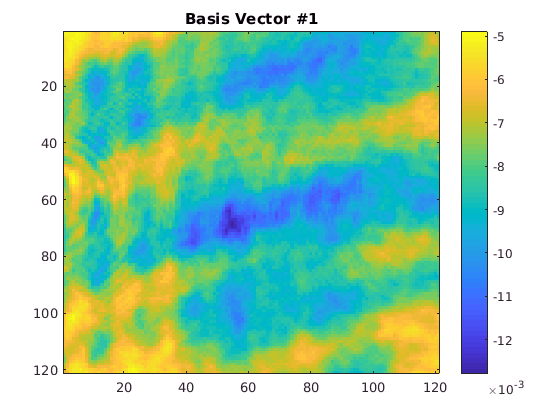

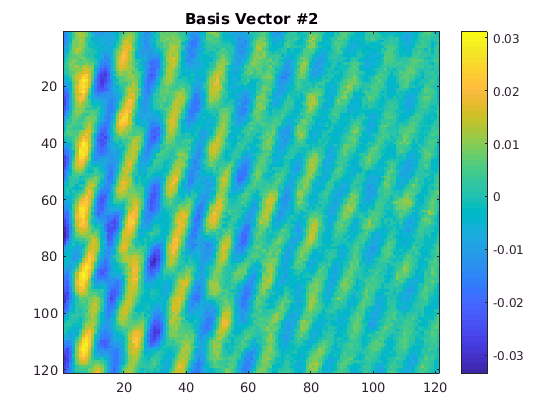

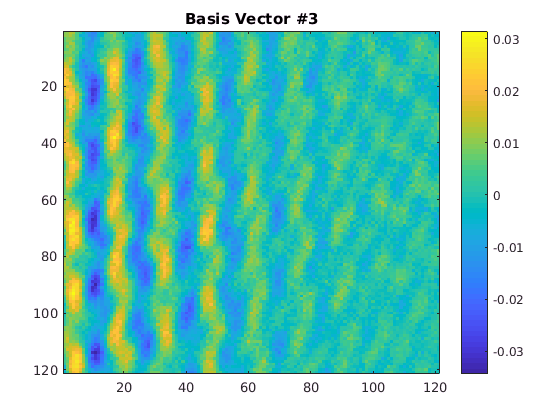

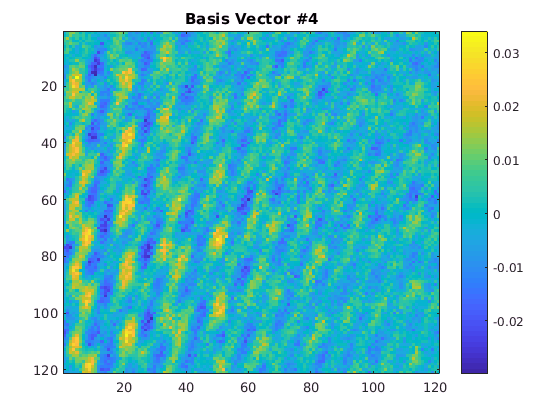

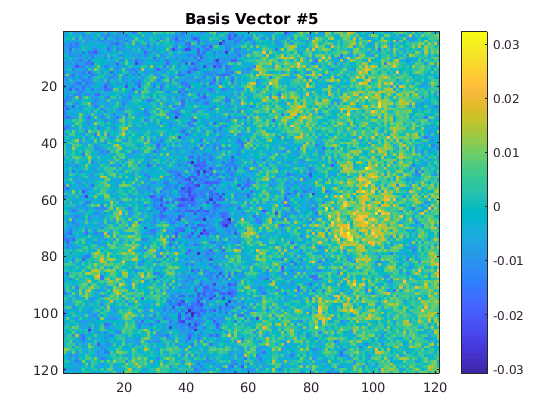

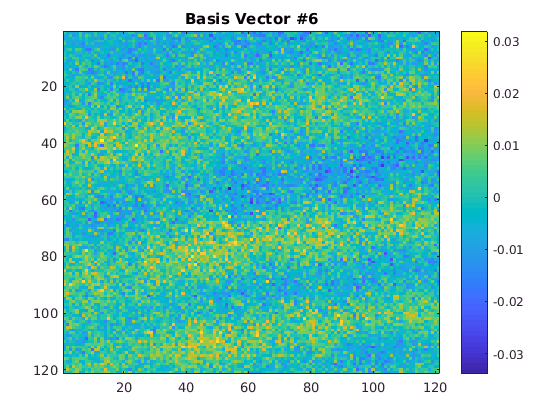

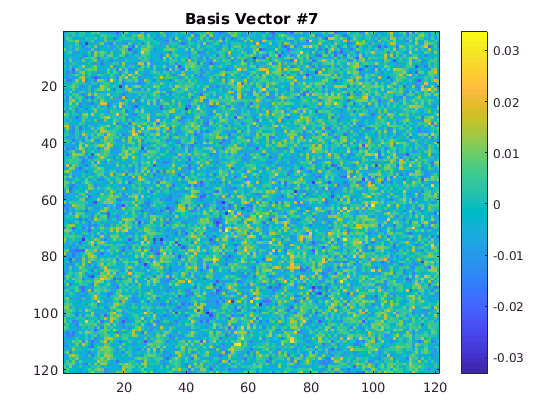

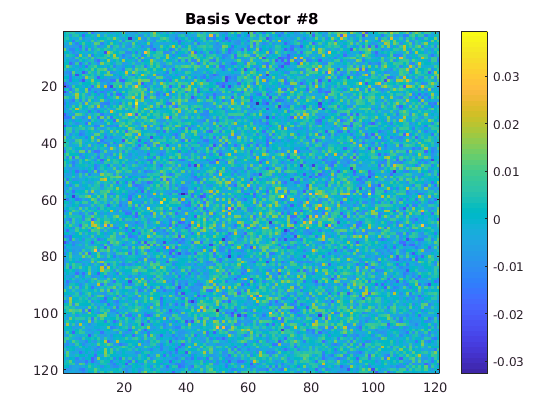

plot_basis_vectors(basis_svd,1:k_max);

disp('Algorithm from Eigenface basis');

Algorithm from Eigenface basis


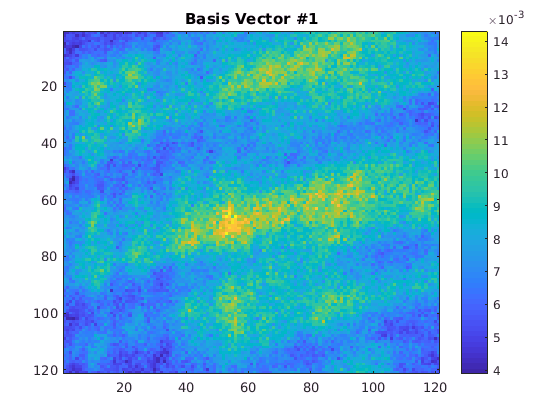

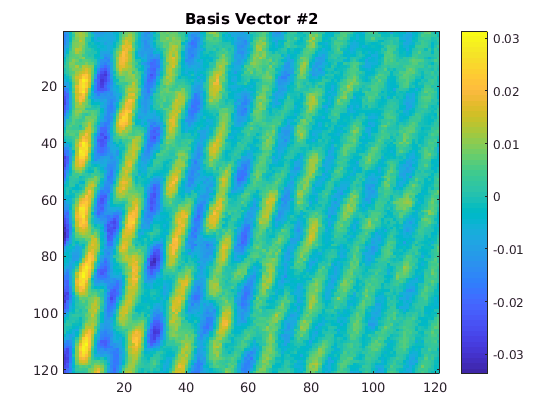

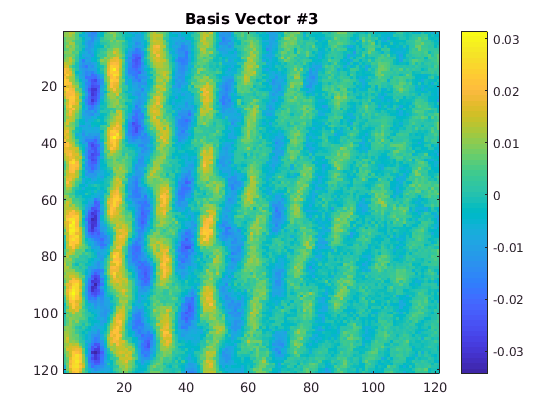

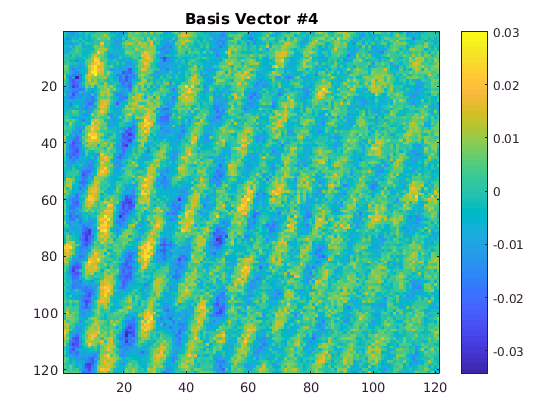

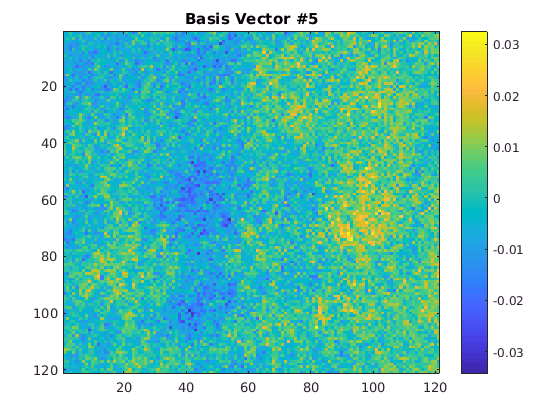

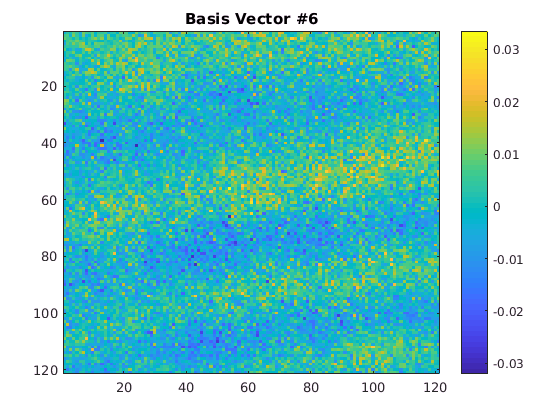

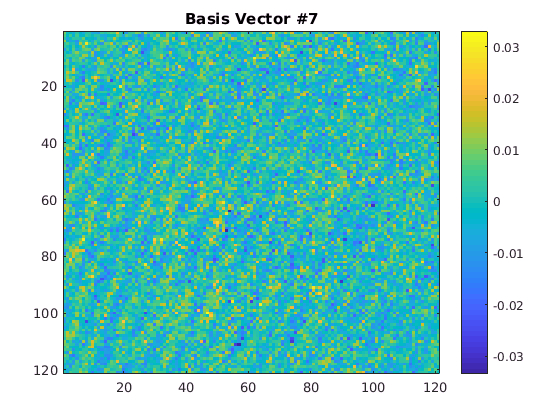

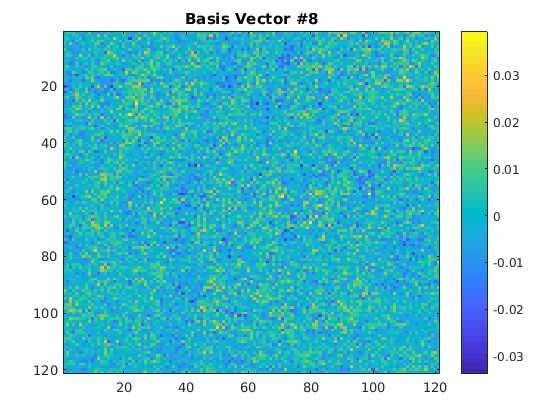

plot_basis_vectors(basis_eigen,1:k_max);

## Basis Input Image Choice

Here we look at what happens if only certain subsets of back images are used to make the basis.  It's clear that using background images taken around the same time as the raw image is important.  Also, using only back images taken soon before the raw image does not work as well as usingthe same number of images taken over a wider spread of time.  Taking a large database of images taken before and after gives the best results, even when they are distilled down to just ~20 basis vectors.

%Looking at residuals for picture 412 using differnt pictures to form basis
disp('Using more or less recent images to make a basis (svd Algorithm)');

Using more or less recent images to make a basis (Cheng Algorithm)


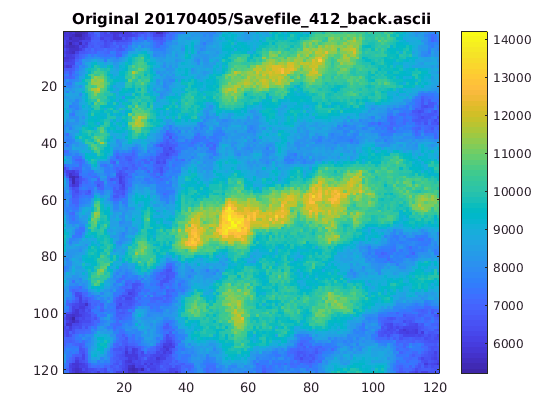

filename=fullfile('20170405','Savefile_412_back.ascii');
% filename=fullfile('20170405','Cool100d100d80PGCZ4.4_1_back.ascii');
max_vectors=20; %Maximum number of vectors to use for basis
filename_pattern=fullfile('20170405','Savefile_%d_back.ascii');

image_in=load_image(filename); %Get data for the background we are re-constructing
plot_image(image_in,['Original ',filename]); %Plot original

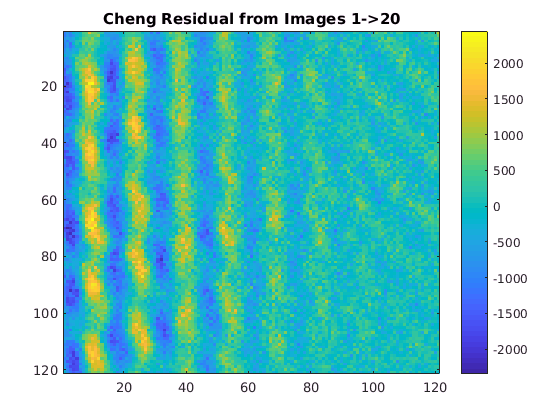

back_region=ones(size(image_in)); %We'll use the full image

%Let's try to re-construct it with the first 20 pictures of that series
k_list=1:20;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd( file_list, back_region, max_vectors);
residual=get_residual_svd(image_in,basis_svd,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'svd Residual from Images 1->20'); %Plot the residual

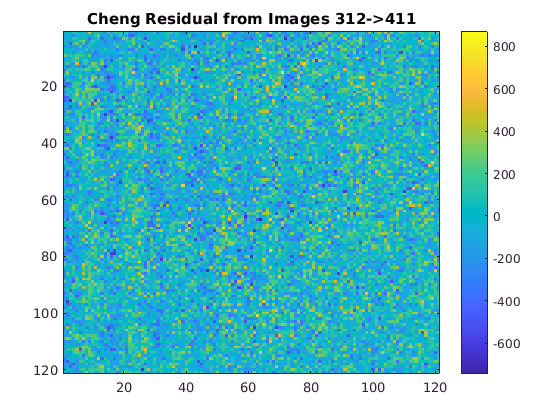


%Now let's try to re-construct it with the 20 pictures right before it
k_list=392:411;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd( file_list, back_region, max_vectors);
residual=get_residual_svd(image_in,basis_svd,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'svd Residual from Images 312->411'); %Plot the residual background

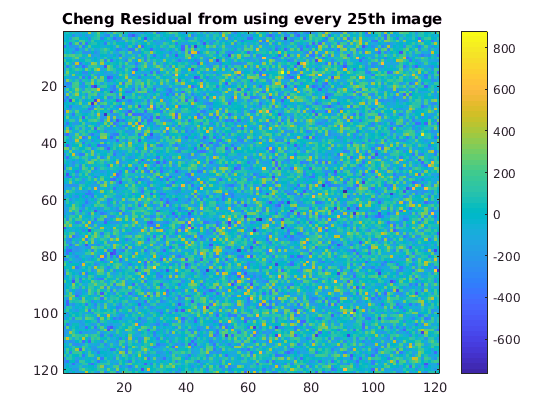


%Now let's try to re-construct it with 20 evenly spaced pictures
k_list=25*(1:20);
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd( file_list, back_region, max_vectors);
residual=get_residual_svd(image_in,basis_svd,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'svd Residual from using every 25th image'); %Plot the residual background

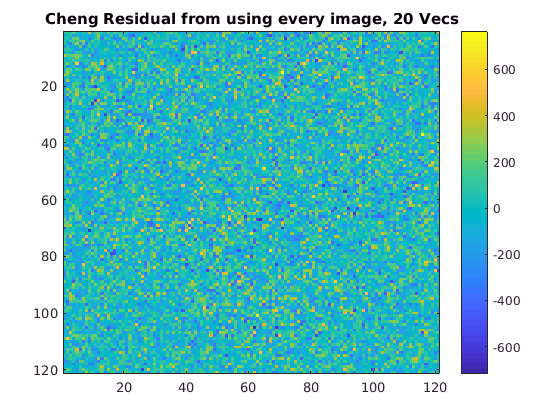


%Now let's try using all 500 images to make only 20 basis vectors
k_list=1:500;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd( file_list, back_region, max_vectors);
residual=get_residual_svd(image_in,basis_svd,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'svd Residual from using every image, 20 Vecs'); %Plot the residual background

% %This is the cell that tried to use v1 to ignore the bottom half.
% %It didn't work but has been surpassed by version 2
% %Doing same thing except ignoring bottom half of image
% filename='Savefile_412_back.ascii';
% atom_region=[61,121,1,121];
% max_vectors=20; %Maximum number of vectors to use for basis
% filename_pattern='Savefile_%d_back.ascii';
%
% image_in=load_image(filename); %Get data for the background we are re-constructing
% plot_image(image_in,'Original'); %Plot original
%
% %Let's try to re-construct it with the first 20 pictures of that series
% k_list=1:20;
% file_list=indices_to_file_list(filename_pattern,k_list);
% basis=make_basis1(file_list,max_vectors);
% residual=get_residual1(image_in,basis,atom_region); %Do projection and subtract the projection from the image
% plot_image(residual,'Residual from Images 1->20 Ignoring bottom half'); %Plot the residual
%
% %Now let's try to re-construct it with the 20 pictures right before it
% k_list=392:411;
% file_list=indices_to_file_list(filename_pattern,k_list);
% basis=make_basis1(file_list,max_vectors);
% residual=get_residual1(image_in,basis,atom_region); %Do projection and subtract the projection from the image
% plot_image(residual,'Residual from Images 392->411 Ignoring bottom half'); %Plot the residual background
%
% %Now let's try to re-construct it with 20 evenly spaced pictures
% k_list=25*(1:20);
% file_list=indices_to_file_list(filename_pattern,k_list);
% basis=make_basis1(file_list,max_vectors);
% residual=get_residual1(image_in,basis,atom_region); %Do projection and subtract the projection from the image
% plot_image(residual,'Residual from using every 25th image Ignoring bottom half'); %Plot the residual background

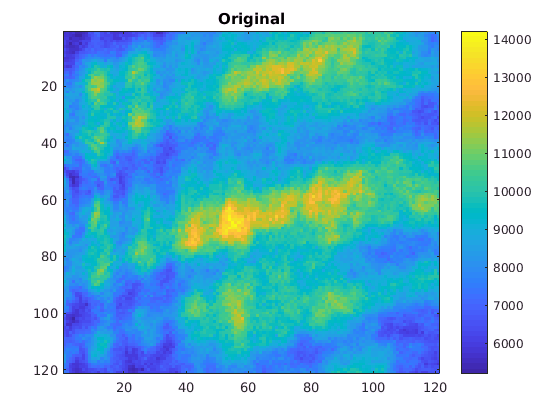

%Doing same thing except ignoring bottom half of image with v2 which does better normalization when ignoring regions
filename=fullfile('20170405','Savefile_412_back.ascii');
% filename=fullfile('20170405','Cool100d100d80PGCZ4.4_1_back.ascii');
row_min=61; row_max=121; col_min=1; col_max=121;
max_vectors=20; %Maximum number of vectors to use for basis
filename_pattern=fullfile('20170405','Savefile_%d_back.ascii');

image_in=load_image(filename); %Get data for the background we are re-constructing
plot_image(image_in,'Original'); %Plot original

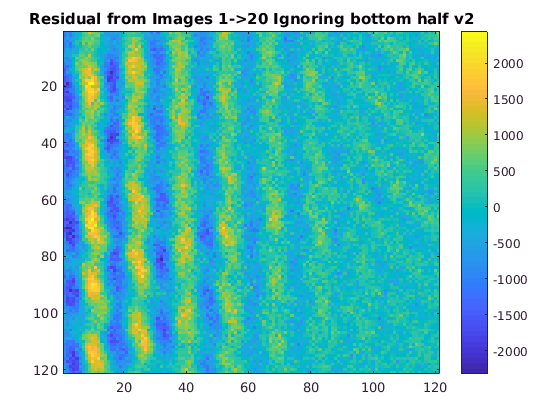


%Creat back_region to mark the bottom half of the image
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
%Let's try to re-construct it with the first 20 pictures of that series
k_list=1:20;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd( file_list, back_region, max_vectors);
residual=get_residual_svd(image_in,basis_svd,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'Residual from Images 1->20 Ignoring bottom half v2'); %Plot the residual

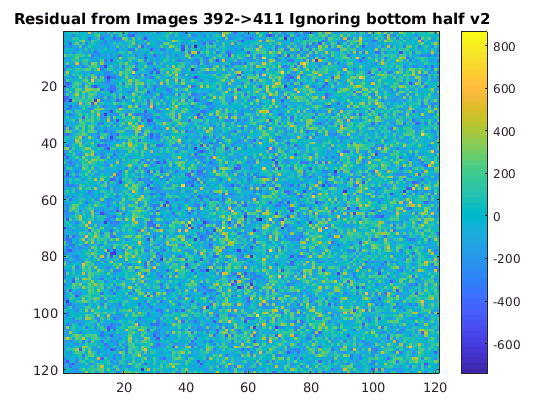


%Now let's try to re-construct it with the 20 pictures right before it
k_list=392:411;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd( file_list, back_region, max_vectors);
residual=get_residual_svd(image_in,basis_svd,back_region); %Do projection and subtract the projection from the image
plot_image(residual,'Residual from Images 392->411 Ignoring bottom half v2'); %Plot the residual

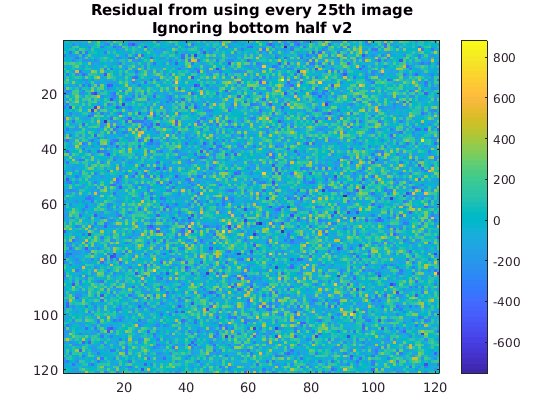


%Now let's try to re-construct it with 20 evenly spaced pictures
k_list=25*(1:20);
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd( file_list, back_region, max_vectors);
residual=get_residual_svd(image_in,basis_svd,back_region); %Do projection and subtract the projection from the image
plot_image(residual,{'Residual from using every 25th image','Ignoring bottom half v2'}); %Plot the residual

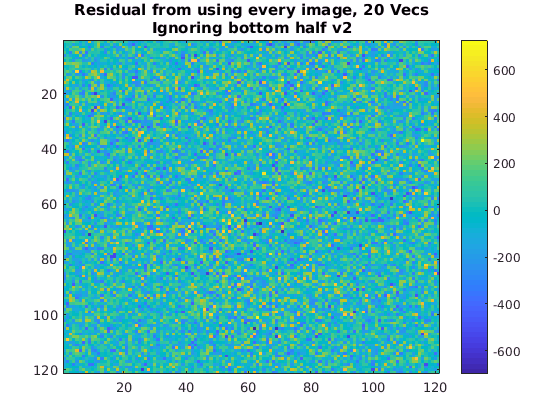


%Now let's try using all 500 images to make only 20 basis vectors
k_list=1:500;
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd( file_list, back_region, max_vectors);
residual=get_residual_svd(image_in,basis_svd,back_region); %Do projection and subtract the projection from the image
plot_image(residual,{'Residual from using every image, 20 Vecs','Ignoring bottom half v2'}); %Plot the residual background

indices=1:10;
%Plot basis vectors (the first k_max of them)
%plot_basis_vectors( basis_svd, indices )

disp('For reference we can see what Poissonian noise looks like');

For reference we can see what Poissonian noise looks like


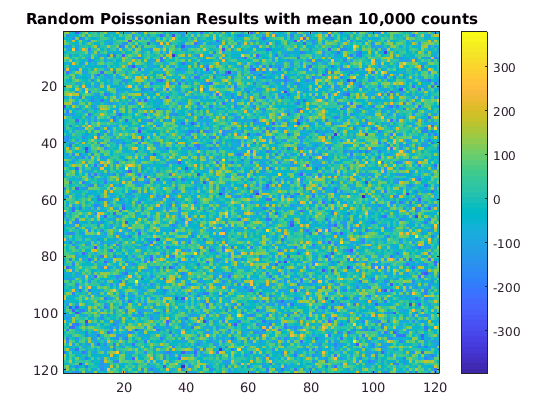

%Requires the statistics and machine learning toolbox
poiss_noise=poissrnd(10e3,121,121)-10e3;
plot_image(poiss_noise,'Random Poissonian Results with mean 10,000 counts');

%Now let's try comparing this technique with the old one for real data
disp('Checking effects from not ignoring atom region');

Checking effects from not ignoring atom region


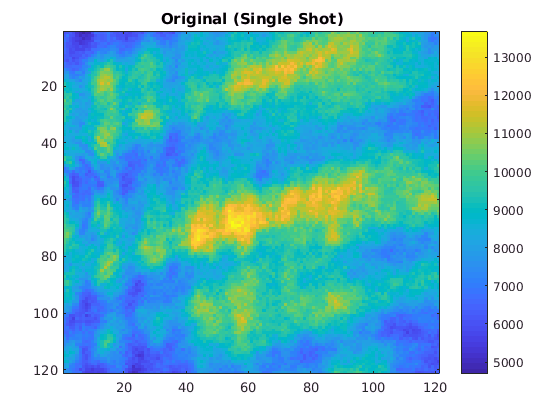

image_name=fullfile('20170405','Cool100d100d80PGCZ4.4_1');
filename=[image_name,'_raw.ascii'];
row_min=40; row_max=60; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis
filename_pattern=fullfile('20170405','Cool100d100d80PGCZ4.4_%d_back.ascii');
k_list=1:15;

image_in=load_image(filename); %Get data for the background we are re-constructing
plot_image(image_in,'Original (Single Shot)'); %Plot original

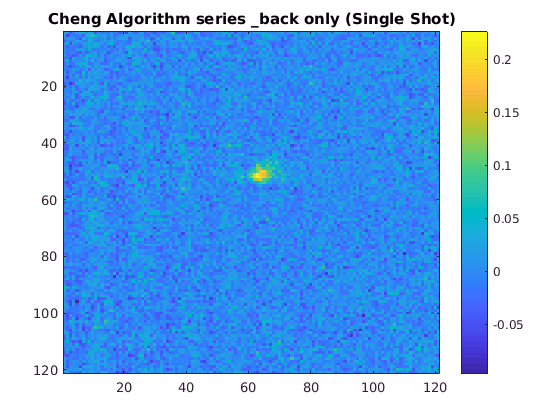


%Old technique
% OD_simple=get_OD_simple(image_name);
% plot_image(OD_simple,'Old Algorithm (Single Shot)');

%SVD technique
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd(file_list,back_region,max_vectors);
OD_svda=get_OD_svd(image_in,basis_svd,back_region);
plot_image(OD_svda,'svd Algorithm series _back only (Single Shot)');

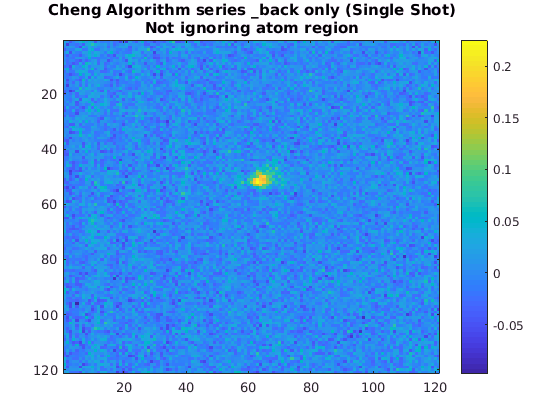



%SVD technique without ignoring atom region
back_region=ones( size(image_in) );
file_list=indices_to_file_list(filename_pattern,k_list);
basis_svd=make_basis_svd(file_list,back_region);
OD_svdb=get_OD_svd(image_in,basis_svd,back_region);
plot_image(OD_svdb,{'svd Algorithm series _back only (Single Shot)','Not ignoring atom region'});

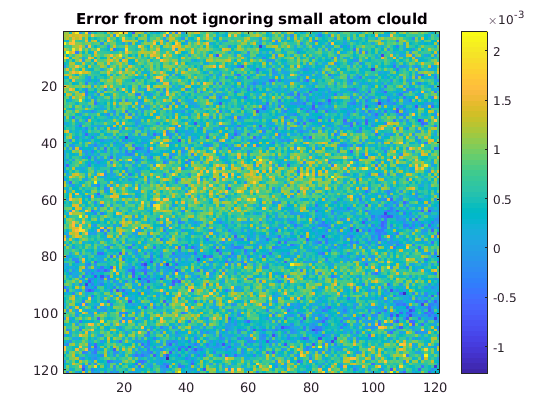


%Difference between ignoring atoms or not ignoring them (for this picture)
plot_image(OD_svda-OD_svdb,'Error from not ignoring small atom clould');

%Real Data again, but now let's use more or fewer basis images
image_name=fullfile('20170405','Cool100d100d80PGCZ4.4_1');
% filename=fullfile('20170405','Savefile_412_raw.ascii');
filename=[image_name,'_raw.ascii'];
row_min=40; row_max=60; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%To use just the background for this single shot, uncomment line below
% file_list={[image_name,'_back.ascii']};
%Background data from this series
filename_pattern1=fullfile('20170405','Cool100d100d80PGCZ4.4_%d_back.ascii');
k_list1=1:15;
file_list1=indices_to_file_list(filename_pattern1,k_list1);
%Background data from another, much longer series
filename_pattern2=fullfile('20170405','Savefile_%d_back.ascii');
% k_list2=20*(1:25);
k_list2=1:500;
file_list2=indices_to_file_list(filename_pattern2,k_list2);
%Uncomment one of the lines below to decide which _back data to use
file_list=file_list1;
% file_list=file_list2;
% file_list=[file_list1;file_list2];

%Plot raw data for reference
image_in=load_image(filename); %Get data for the background we are re-constructing
plot_image(image_in,{'Original','Comparing different basis inputs'}); %Plot original


%Old technique
OD_simple=get_OD_simple(image_name);
% plot_image(OD_simple,'Old Algorithm');

%SVD technique
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
basis_svd=make_basis_svd(file_list,back_region,max_vectors);
OD_svd=get_OD_svd(image_in,basis_svd,back_region);
plot_image(OD_svd,{'svd Algorithm','various *_back, see code'});


%Eigenfaces technique
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
[basis_eig,mean_back,~] = make_basis_eig(file_list,back_region,max_vectors);
OD_eig=get_OD_eig(image_in,basis_eig,mean_back,back_region);
plot_image(OD_eig,{'Eigenface Algorithm','various *_back, see code'});


%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_simple,'Old',limits,fig);
plot_cross_sections(OD_svd,'svd',limits,fig);
plot_cross_sections(OD_eig,'Eigenfaces',limits,fig);

fig=figure();

%Cool* and Save* data
file_list=[file_list1;file_list2];
basis_svd=make_basis_svd(file_list,back_region,max_vectors);
OD_svdcs=get_OD_svd(image_in,basis_svd,back_region);
[basis_eig,mean_back,~] = make_basis_eig(file_list,back_region,max_vectors);
OD_eigcs=get_OD_eig(image_in,basis_eig,mean_back,back_region);
plot_cross_sections(OD_svdcs,'svd Cool*+Save*',limits,fig);
plot_cross_sections(OD_eigcs,'Eigenfaces Cool*+Save*',limits,fig);

%Now just the Cool*_back.ascii data
file_list=file_list1;
basis_svd=make_basis_svd(file_list,back_region,max_vectors);
OD_svdc=get_OD_svd(image_in,basis_svd,back_region);
[basis_eig,mean_back,~] = make_basis_eig(file_list,back_region,max_vectors);
OD_eigc=get_OD_eig(image_in,basis_eig,mean_back,back_region);
plot_cross_sections(OD_svdc,'svd Cool*',limits,fig);
plot_cross_sections(OD_eigc,'Eigenfaces Cool*',limits,fig);

%Now just the Save*_back.ascii data
file_list=file_list1;
basis_svd=make_basis_svd(file_list,back_region,max_vectors);
OD_svds=get_OD_svd(image_in,basis_svd,back_region);
[basis_eig,mean_back,~] = make_basis_eig(file_list,back_region,max_vectors);
OD_eigs=get_OD_eig(image_in,basis_eig,mean_back,back_region);
plot_cross_sections(OD_svds,'svd Save*',limits,fig);
plot_cross_sections(OD_eigs,'Eigenfaces Save*',limits,fig);

%Now using real data that may actually make it into the paper
%This set has no_atoms data to help our old algorithm
disp('Comparing to old Algorithm for many shots averaged');

Comparing to old Algorithm for many shots averaged


image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
no_atom_name=fullfile('20170406','NoAtoma1');
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Old technique
OD_simple=load_image([image_name,'.txt']);
no_atom=load_image([no_atom_name,'.txt']);
plot_image(OD_simple,'Old Algorithm');

OD_simple=OD_simple-no_atom;
plot_image(OD_simple,'Old Algorithm With No-Atom Series');


%Setting up file lists, choose whether to use the back data from this series, the
%no-atom series or both by uncommenting one of the file_list assignements below
filename_pattern1=[image_name,'_%d_back.ascii'];
k_list1=1:150;
% k_list1=7*(1:20);
file_list1=indices_to_file_list(filename_pattern1,k_list1);
filename_pattern2=[no_atom_name,'_%d_back.ascii'];
k_list2=1:200;
% k_list2=10*(1:20);
file_list2=indices_to_file_list(filename_pattern2,k_list2);
% file_list=file_list1; %back data from this series only
% file_list=file_list2; %back data from the no-atom series only
file_list=[file_list1;file_list2]; %Both this series and no-atom series


%SVDtechnique
back_region=make_back_region( image_in, row_min, row_max, col_min ,col_max);
basis_svd=make_basis_svd(file_list,back_region,max_vectors);

%Make list of images with atoms, remove background from each, then average
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
k_max=length(atom_file_list);
[n_rows, n_cols]=size( load_image(file_list{1}) );
OD_svd_array=zeros(n_rows,n_cols,k_max);
for k=1:k_max
    filename=atom_file_list{k};
    image_in=load_image(filename);
    OD_svd_array(:,:,k)=get_OD_svd(image_in,basis_svd,back_region);
end
OD_svd=mean(OD_svd_array,3);
plot_image(OD_svd,'svd Algorithm');


%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_simple,'Old',limits,fig);
plot_cross_sections(OD_svd,'svd',limits,fig);

%Seeing if averaging the raw images before or after background removal changes anything
disp('Comparing doing background removal before or after averaging images');

Comparing doing background removal before or after averaging images


image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
no_atom_name=fullfile('20170406','NoAtoma1');
% filename=[image_name,'_raw.ascii'];
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=10; %Maximum number of vectors to use for basis

%Setting up file lists, choose whether to use the back data from this series, the
%no-atom series or both by uncommenting one of the file_list assignements below
filename_pattern1=[image_name,'_%d_back.ascii'];
k_list1=1:150;
% k_list1=7*(1:20);
file_list1=indices_to_file_list(filename_pattern1,k_list1);
filename_pattern2=[no_atom_name,'_%d_back.ascii'];
k_list2=1:200;
% k_list2=10*(1:20);
file_list2=indices_to_file_list(filename_pattern2,k_list2);
% file_list=file_list1; %back data from this series only
% file_list=file_list2; %back data from the no-atom series only
file_list=[file_list1;file_list2]; %Both this series and no-atom series

%SVD technique
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
basis_svd=make_basis_svd(file_list,back_region,max_vectors);
[basis_eig,mean_back,~]=make_basis_eig(file_list,back_region,max_vectors);

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
k_max=length(atom_file_list);
[n_rows, n_cols]=size( load_image(file_list{1}) );
raw_array=zeros(n_rows,n_cols,k_max);
OD_svd_array=zeros(n_rows,n_cols,k_max);
OD_eig_array=zeros(n_rows,n_cols,k_max);
for k=1:k_max
    filename=atom_file_list{k};
    image_in=load_image(filename);
    raw_array(:,:,k)=image_in;
    OD_svd_array(:,:,k)=get_OD_svd(image_in,basis_svd,back_region);
    OD_eig_array(:,:,k)=get_OD_eig(image_in,basis_eig,mean_back,back_region);
end
raw_mean=mean(raw_array,3);
OD_svd_before=mean(OD_svd_array,3);
OD_eig_before=mean(OD_eig_array,3);
OD_svd_after=get_OD_svd(raw_mean,basis_svd,back_region);
OD_eig_after=get_OD_eig(raw_mean,basis_eig,mean_back,back_region);

%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_svd_before,'OD_svd before',limits,fig);
plot_cross_sections(OD_svd_after,'OD_svd after',limits,fig);
plot_cross_sections(OD_eig_before,'OD_svd before',limits,fig);
plot_cross_sections(OD_eig_after,'OD_eig after',limits,fig);

%Mega-basis using all the _back images
disp('Seeing if using all the */*_back.ascii files improves the image');

Seeing if using all the */*_back.ascii files improves the image


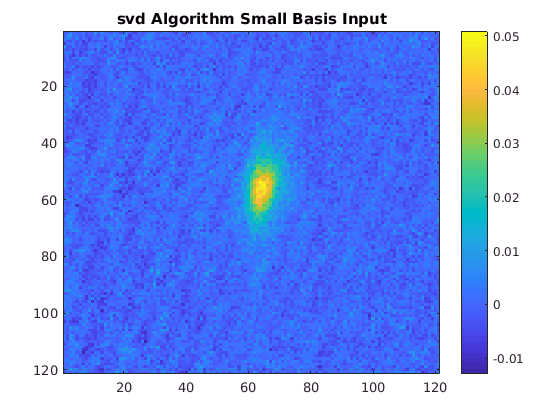

image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
back_file_pattern=fullfile('2017040*','*_back.ascii');
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists, choose whether to use the back data from this series, the
%no-atom series or both by uncommenting one of the file_list assignements below
filename_pattern1=[image_name,'_%d_back.ascii'];
k_list1=1:150;
file_list1=indices_to_file_list(filename_pattern1,k_list1);
file_list2=get_file_list(back_file_pattern);

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
basis_svd_small=make_basis_svd(file_list1,back_region,max_vectors);
basis_svd_big=make_basis_svd(file_list2,back_region,max_vectors);
[basis_eig_small,mean_back_small,~]=make_basis_eig(file_list1,back_region,max_vectors);
[basis_eig_big,mean_back_big,~]=make_basis_eig(file_list2,back_region,max_vectors);

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
raw_mean=get_mean_image(atom_file_list);
OD_svd_small=get_OD_svd(raw_mean,basis_svd_small,back_region);
OD_svd_big=get_OD_svd(raw_mean,basis_svd_big,back_region);
OD_eig_small=get_OD_eig(raw_mean,basis_eig_small,mean_back_small,back_region);
OD_eig_big=get_OD_eig(raw_mean,basis_eig_big,mean_back_big,back_region);

%Plot the resulting images
plot_image(OD_svd_small,'svd Algorithm Small Basis Input');

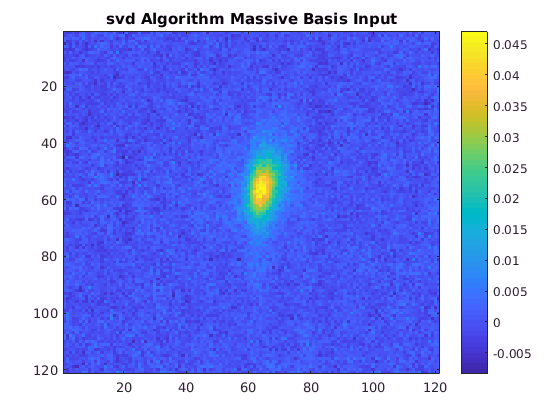

plot_image(OD_svd_big,'svd Algorithm Massive Basis Input');

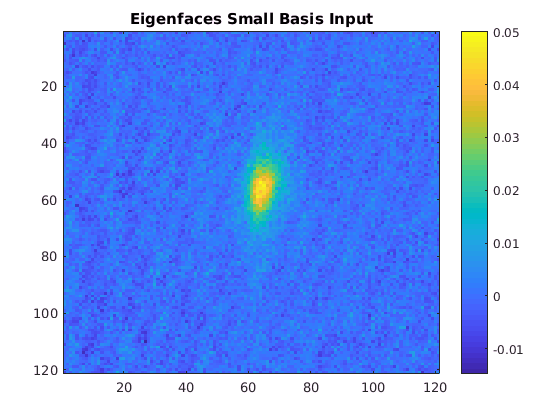

plot_image(OD_eig_small,'Eigenfaces Small Basis Input');

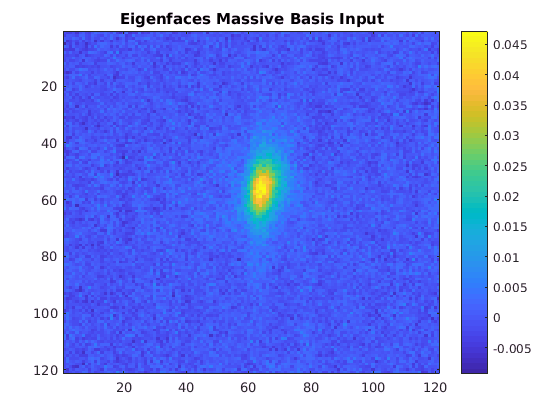

plot_image(OD_eig_big,'Eigenfaces Massive Basis Input');

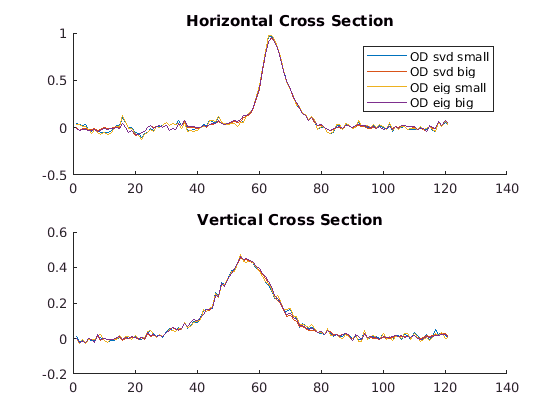


%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_svd_small,'OD svd small',limits,fig);
plot_cross_sections(OD_svd_big,'OD svd big',limits,fig);
plot_cross_sections(OD_eig_small,'OD eig small',limits,fig);
plot_cross_sections(OD_eig_big,'OD eig big',limits,fig);

%Let's compare some of the basis vectors from the two big bases
disp('Looking at basis vectors from the two different algorithms');
disp('They seem to be the same up to a factor of -1 except for the');
disp('first basis vector which may differ by mean_back');
% indices=1:20;
indices=[2];
%Plot basis vectors
plot_basis_vectors( basis_eig_big, indices );
plot_basis_vectors( basis_svd_big, indices );

%Seeing if using every 10th image from the mega-basis gives similar results
disp('Seeing if using every 10th the */*_back.ascii files works as well');
image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
back_file_pattern=fullfile('2017040*','*_back.ascii');
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists, choose whether to use the back data from this series, the
%no-atom series or both by uncommenting one of the file_list assignements below
filename_pattern1=[image_name,'_%d_back.ascii'];
k_list1=1:150;
file_list1=indices_to_file_list(filename_pattern1,k_list1);
file_list2=get_file_list(back_file_pattern);
%shorten file_lists
% file_list1=file_list1(1:10:length(file_list1));
file_list10=file_list2(1:10:length(file_list2));

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
basis_svd_10=make_basis_svd(file_list10,back_region,max_vectors);
% basis_svd_big=make_basis_svd(file_list2,back_region,max_vectors);
[basis_eig_10,mean_back_10,~]=make_basis_eig(file_list10,back_region,max_vectors);
% [basis_eig_big,mean_back_big,~]=make_basis_eig(file_list2,back_region,max_vectors);

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
raw_mean=get_mean_image(atom_file_list);
OD_svd_10=get_OD_svd(raw_mean,basis_svd_10,back_region);
OD_svd_big=get_OD_svd(raw_mean,basis_svd_big,back_region);
OD_eig_10=get_OD_eig(raw_mean,basis_eig_10,mean_back_10,back_region);
OD_eig_big=get_OD_eig(raw_mean,basis_eig_big,mean_back_big,back_region);

%Plot the resulting images
plot_image(OD_svd_10,'svd Algorithm Every 10th Basis Input');
plot_image(OD_svd_big,'svd Algorithm Massive Basis Input');
plot_image(OD_eig_10,'Eigenfaces Every 10th Basis Input');
plot_image(OD_eig_big,'Eigenfaces Massive Basis Input');

%Plot their cross-sections
fig=figure();
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_svd_10,'OD svd every 10th image',limits,fig);
plot_cross_sections(OD_svd_big,'OD svd big',limits,fig);
plot_cross_sections(OD_eig_10,'OD eig every 10th image',limits,fig);
plot_cross_sections(OD_eig_big,'OD eig big',limits,fig);

%Now that I'm very convinced svd and Eigenfaces give similar output, I'd
%like to figure out which one is fastest for large inputs
disp('Figuring out whether svd or Eigenfaces is faster for large input');
%Pick a file_list
file_list=file_list2;
%Make function handles so we can use timeit()
svd_handle=@() make_basis_svd(file_list,back_region,max_vectors);
eig_handle=@() make_basis_eig(file_list,back_region,max_vectors);
%Now let's time the functions
svd_time=timeit(svd_handle,1); %1 because make_basis_eig has 1 output
eig_time=timeit(eig_handle,3); %3 because make_basis_eig has 3 outputs
%Display the results
fprintf('svd took %f seconds\n',svd_time);
fprintf('Eigenfaces took %f seconds\n',eig_time);

profile on
[a,b,c]=make_basis_eig(file_list,back_region,max_vectors);
profile off
profile viewer

profile on
a=make_basis_svd(file_list,back_region,max_vectors);
profile off
profile viewer

fprintf('Turns out that eigenfaces is much faster.  With ~3000 images eigenfaces\n');
fprintf('it only takes 15 seconds and is mainly limited by how long it takes to\n');
fprintf('get the data off the hard drive.  The svd algorithm takes 30 seconds\n');
fprintf('and is not hard-drive limited for the same 3000 images data set (mainly\n');
fprintf('it is limited by how long svd() takes). This may partially be due to my\n');
fprintf('particular implementation, but either way I will just use eigenfaces now\n');
fprintf('\n\n\n\n');

%Now let's see if including the */*_noise.ascii images improves things at all
disp('Seeing if adding the */*_noise.ascii files to the basis input improves the results');
image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
back_file_pattern=fullfile('2017040*','*_back.ascii');
noise_file_pattern=fullfile('2017040*','*_noise.ascii');
row_min=30; row_max=80; col_min=50; col_max=80; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists
file_list_back=get_file_list(back_file_pattern);
file_list_noise=get_file_list(noise_file_pattern);
file_list_both=[file_list_back,file_list_noise];

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
basis_svd_back=make_basis_svd(file_list_back,back_region,max_vectors);
basis_svd_both=make_basis_svd(file_list_both,back_region,max_vectors);
[basis_eig_back,mean_back_back,~]=make_basis_eig(file_list_back,back_region,max_vectors);
[basis_eig_both,mean_back_both,~]=make_basis_eig(file_list_both,back_region,max_vectors);

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_%d_raw.ascii'];
k_list=1:150;
atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
raw_mean=get_mean_image(atom_file_list);
OD_svd_back=get_OD_svd(raw_mean,basis_svd_back,back_region);
OD_svd_both=get_OD_svd(raw_mean,basis_svd_both,back_region);
OD_eig_back=get_OD_eig(raw_mean,basis_eig_back,mean_back_back,back_region);
OD_eig_both=get_OD_eig(raw_mean,basis_eig_both,mean_back_both,back_region);

%Plot the resulting images
plot_image(OD_svd_back,'svd Algorithm back only');
plot_image(OD_svd_both,'svd Algorithm back and nosie');
plot_image(OD_eig_back,'Eigenfaces back only');
plot_image(OD_eig_both,'Eigenfaces back and nosie');

%Plot their cross-sections
%They overlap very well so I'll plot each separately before plotting together
%so that it's clear that you can't see all the curves because they overlap
fig=figure(); %eigenfaces results only
limits=[row_min,row_max,col_min,col_max];
plot_cross_sections(OD_eig_back,'OD eig back only',limits,fig);
plot_cross_sections(OD_eig_both,'OD eig both',limits,fig);
fig=figure(); %svd results only
plot_cross_sections(OD_svd_back,'OD svd back only',limits,fig);
plot_cross_sections(OD_svd_both,'OD svd both',limits,fig);
fig=figure(); %Overlaid eigenfaces and svd
plot_cross_sections(OD_svd_back,'OD svd back only',limits,fig);
plot_cross_sections(OD_svd_both,'OD svd both',limits,fig);
plot_cross_sections(OD_eig_back,'OD eig back only',limits,fig);
plot_cross_sections(OD_eig_both,'OD eig both',limits,fig);

% indices=1:20;
indices=[5];
%Plot basis vectors
plot_basis_vectors( basis_eig_both, indices );
plot_basis_vectors( basis_svd_both, indices );

%Now let's see if subtracting the noise from all the images helps (haven't finished this yet)
disp('Seeing if subtracting the */*_noise.ascii files to the basis input improves the results');
disp('have not finished this yet, I will have to come back to it');
% image_name=fullfile('20170406','Getter4p1BackRefOff6Z0p24Cool100d100d300XSlowOff2p2a1');
% back_file_pattern=fullfile('2017040*','*_back.ascii');
% noise_file_pattern=fullfile('2017040*','*_noise.ascii');
% row_min=30; row_max=80; col_min=50; col_max=80; %atom region
% max_vectors=20; %Maximum number of vectors to use for basis
% 
% %Setting up file lists, choose whether to use the back data from this series, the
% %no-atom series or both by uncommenting one of the file_list assignements below
% file_list_back=get_file_list(back_file_pattern);
% file_list_noise=get_file_list(noise_file_pattern);
% 
% %Makes basis (and mean_back) for each set of inputs
% back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
% [basis_eig_back,mean_back_back,~]=make_basis_eig(file_list_back,back_region,max_vectors);
% [basis_eig_both,mean_back_both,~]=make_basis_eig(file_list_both,back_region,max_vectors);
% 
% %Make lists of images with atoms with/without background removed
% atom_filename_pattern=[image_name,'_%d_raw.ascii'];
% k_list=1:150;
% atom_file_list=indices_to_file_list(atom_filename_pattern,k_list);
% raw_mean=get_mean_image(atom_file_list);
% OD_eig_back=get_OD_eig(raw_mean,basis_eig_back,mean_back_back,back_region);
% OD_eig_both=get_OD_eig(raw_mean,basis_eig_both,mean_back_both,back_region);
% 
% %Plot the resulting images
% plot_image(OD_eig_back,'Eigenfaces back only');
% plot_image(OD_eig_both,'Eigenfaces back and nosie');
% 
% %Plot their cross-sections
% %They overlap very well so I'll plot each separately before plotting together
% %so that it's clear that you can't see all the curves because they overlap
% fig=figure(); %eigenfaces results only
% limits=[row_min,row_max,col_min,col_max];
% plot_cross_sections(OD_eig_back,'OD eig back only',limits,fig);
% plot_cross_sections(OD_eig_both,'OD eig both',limits,fig);

%Looking at data from 13 April 2017
disp('Looking at data from pancakes');
back_file_pattern=fullfile('*','*_back.ascii');
row_min=30; row_max=80; col_min=50; col_max=90; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists
file_list_back=get_file_list(back_file_pattern);

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
[basis_eig,mean_back,~]=make_basis_eig(file_list_back,back_region,max_vectors);

%Series to average/remove background
% image_name=fullfile('20170413','BackRefLensOff75milCool100d100d100YRelease3msSlowOff1p3a1');
image_name=fullfile('20170413','BackRefLensOff75milCool100d100d100YRelease13msSlowOff1p3a1');
limits=[row_min,row_max,col_min,col_max]; %for integrating over directions

%Make lists of images with atoms with/without background removed
atom_filename_pattern=[image_name,'_*_raw.ascii'];
atom_file_list=get_file_list(atom_filename_pattern);
raw_mean=get_mean_image(atom_file_list);
OD_eig=get_OD_eig(raw_mean,basis_eig,mean_back,back_region);

%Plot the resulting images
plot_image(OD_eig,image_name);
plot_cross_sections(OD_eig,image_name,limits);

% save_image(OD_eig,'BackRefLensOff75milCool100d100d100YRelease13msSlowOff1p3a1_eig.ascii');

%Testing if dlmread is faster than the auto-generated load_image()
disp('Testing functions for reading image data off of the hard drive');

Testing functions for reading image data off of the hard drive



%Make a file_list
back_file_pattern=fullfile('20170414','*_back.ascii');
back_file_pattern=fullfile('*','*_back.ascii');
file_list=get_file_list(back_file_pattern);

%Start profiling
profile on
for k=1:length(file_list)
    filename=file_list{k};
    temp=load_image(filename);
end
profile off
profile viewer

load_image( fullfile('20170412','Savefile_45_back.ascii'),true );

profile on
for k=1:length(file_list)
    filename=file_list{k};
    temp=dlmread(filename,'\t');
end
profile off
profile viewer
disp('Turns out the auto-generated load_image is faster than dlmread');

Turns out the auto-generated load_image is faster than dlmread


disp('I believe that load_image will only work for 121x121 images though');

I believe that load_image will only work for 121x121 images though


%Seeing if we can use the data from April 5th and 6th to remove background on data from the 13th
disp('Seeing if data from the 5th and 6th can remove background from 13th');

Seeing if data from the 5th and 6th can remove background from 13th


back_file_pattern=fullfile('2017040*','*_back.ascii');
row_min=30; row_max=80; col_min=50; col_max=90; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists
file_list_back=get_file_list(back_file_pattern);

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
[basis_eig,mean_back,~]=make_basis_eig(file_list_back,back_region,max_vectors);

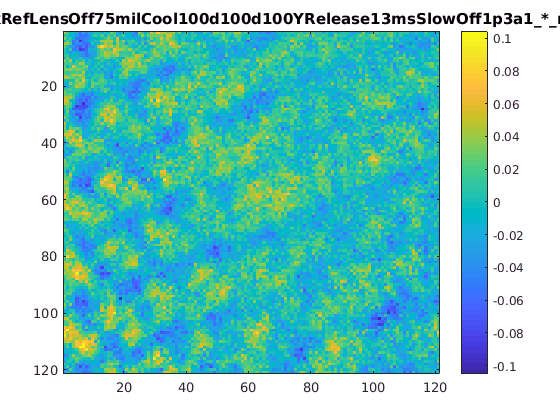

%Series to average/remove background
series_name=fullfile('20170413','BackRefLensOff75milCool100d100d100YRelease13msSlowOff1p3a1_*_raw.ascii');
limits=[row_min,row_max,col_min,col_max]; %for integrating over directions

atom_OD=process_series_eig(series_name,basis_eig,mean_back,back_region);
plot_image(atom_OD,series_name);

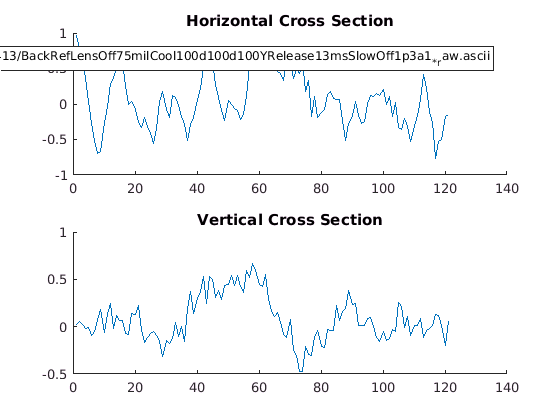

plot_cross_sections(atom_OD,series_name,limits);

%Process data from 14th April 2017 for Alban
disp('Processing data from 14th April 2017 for Alban');
back_file_pattern=fullfile('2017041*','*_back.ascii');
row_min=1; row_max=100; col_min=40; col_max=90; %atom region
max_vectors=20; %Maximum number of vectors to use for basis

%Setting up file lists
file_list_back=get_file_list(back_file_pattern);

%Makes basis (and mean_back) for each set of inputs
back_region=make_back_region(image_in,row_min,row_max,col_min,col_max);
[basis_eig,mean_back,~]=make_basis_eig(file_list_back,back_region,max_vectors);

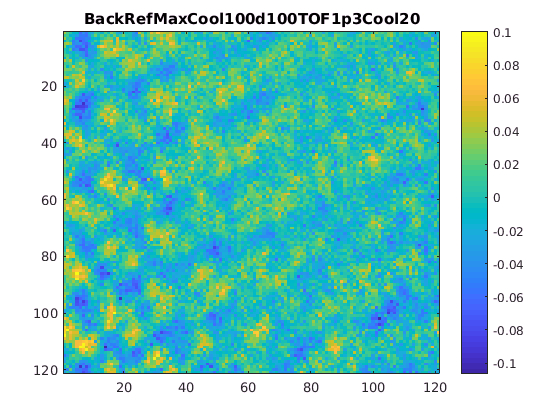

%Series to average/remove background
% series_name='BackRefMaxCool100d100TOF1p3Cool1000';
% series_name='BackRefMaxCool100d100TOF1p3Cool500';
% series_name='BackRefMaxCool100d100TOF1p3Cool300';
% series_name='BackRefMaxCool100d100TOF1p3Cool200';
% series_name='BackRefMaxCool100d100TOF1p3Cool150';
% series_name='BackRefMaxCool100d100TOF1p3Cool100';
% series_name='BackRefMaxCool100d100TOF1p3Cool80';
% series_name='BackRefMaxCool100d100TOF1p3Cool60';
% series_name='BackRefMaxCool100d100TOF1p3Cool40';
series_name='BackRefMaxCool100d100TOF1p3Cool20';
% series_name='BackRefMaxCool100d100TOF1p3Cool1';
% series_name='Savefile';
series_fullname=fullfile('20170414',[series_name,'_*_raw.ascii']);
limits=[row_min,row_max,col_min,col_max]; %for integrating over directions

%Average, remove background, and save the data
save_name=[series_name,'_eig.ascii'];
atom_OD=process_series_eig(series_fullname,basis_eig,mean_back,back_region);
plot_image(atom_OD,series_name);

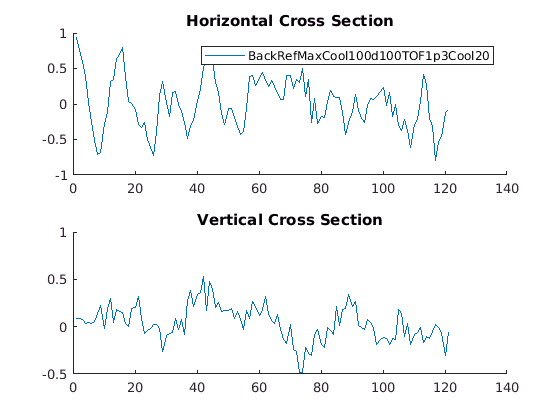

plot_cross_sections(atom_OD,series_name,limits);

% save_image(atom_OD,save_name);

## Checking if changing the integration limits when plotting cross sections helps

It doesn't seem to help much.  Making it much larger increases the fringes slightly (at least for this data) instead of averaging them out.  The fringe amplitude is possibly roughly due to averaging over a non-integer multiple of fringe periods.  Using only two lines of data makes the results noisier and the fringes are still apparent.

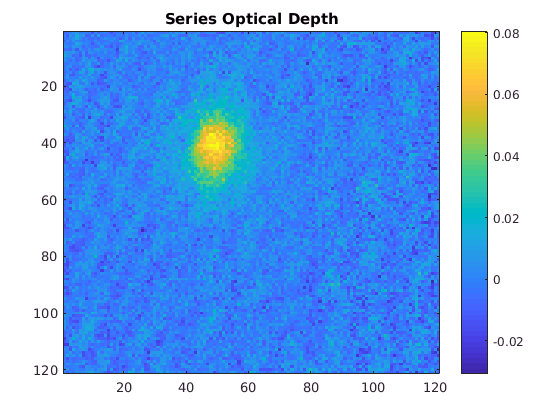

image_in=zeros(121,121); %dummy image with correct dimensions
row_min=20; row_max=60; col_min=30; col_max=70;
back_region = make_back_region(image_in,row_min,row_max,col_min,col_max);
max_vectors = 20; %20 is typically a good number for this
ls_pattern = fullfile('20170718','*_back.ascii');
file_list = get_file_list(ls_pattern);
[basis_eig, mean_back] = make_basis_eig(file_list,back_region,max_vectors);
series_name = fullfile('20170718','Cool100X100Y80TOF1p5Z0.25_*_raw.ascii');
OD_eig = process_series_eig(series_name,basis_eig,mean_back,back_region);
plot_image(OD_eig,'Series Optical Depth');

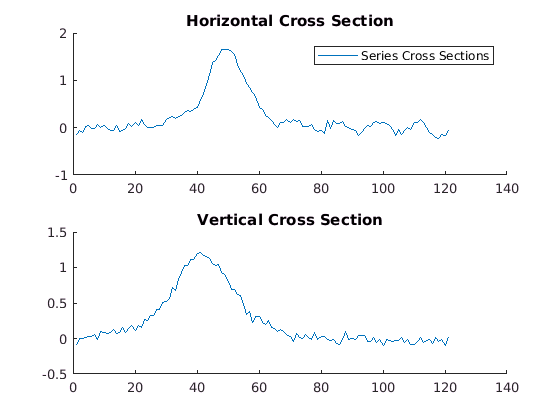

limits = [row_min,row_max,col_min,col_max];
plot_cross_sections(OD_eig,'Series Cross Sections',limits);

disp('Changing cross section integration limits');

Changing cross section integration limits


disp('Normalization adjusted by hand to make curves comparable heights');

Normalization adjusted by hand to make curves comparable heights


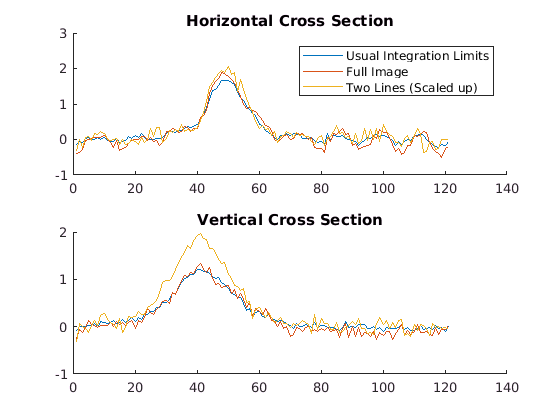

limits = [row_min,row_max,col_min,col_max];
fig=plot_cross_sections(OD_eig,'Usual Integration Limits',limits);
limits = [1,121,1,121];
plot_cross_sections(OD_eig,'Full Image',limits,fig);
limits = [40,41,50,51];
plot_cross_sections(13*OD_eig,'Two Lines (Scaled up)',limits,fig);

## Let's see if adjusting the atom region improves things

Turns out it keeps the shape of the cross sections mostly the same, but making the atom region larger slightly shifts the curves upward.  I'm not sure why that is the case.  It also does change the fringes slightly, at the few percent level a

However, once the atom_region is a reasonable size that we'd typically use for this data (i.e. 40x40 pixels) the curves don't change much when increasing the atom region size, which is good.  Subtracting two images with large but differently-sized atom regions causes the OD values to vary on the level of only a few percent.   Therefore this doesn't seem to be the issue.

disp('Varying atom region size');

Varying atom region size


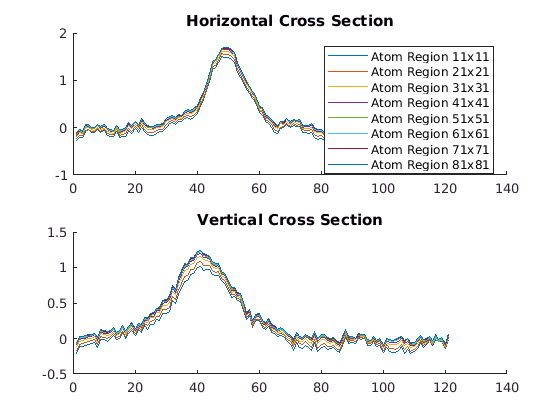

image_in=zeros(121,121); %dummy image with correct dimensions
max_vectors = 20; %20 is typically a good number for this
ls_pattern = fullfile('20170718','*_back.ascii');
file_list = get_file_list(ls_pattern);
series_name = fullfile('20170718','Cool100X100Y80TOF1p5Z0.25_*_raw.ascii');
limits=[20,60,30,70]; %Limits for  cross section integration
row_center=50; col_center=42;
fig=figure();

kmax=8;
ODs_atom_region_size=zeros(121,121,kmax);
for k=1:kmax
    row_min=row_center-5*k; row_max=row_center+5*k;
    col_min=col_center-5*k; col_max=col_center+5*k;
    back_region = make_back_region(image_in,row_min,row_max,col_min,col_max);
    [basis_eig, mean_back] = make_basis_eig(file_list,back_region,max_vectors);
    OD_eig = process_series_eig(series_name,basis_eig,mean_back,back_region);
    ODs_atom_region_size(:,:,k)=OD_eig;
    plot_title=sprintf('Atom Region %dx%d',row_max-row_min+1,col_max-col_min+1);
%     plot_image(OD_eig,plot_title);
%     plot_cross_sections(OD_eig,plot_title,limits);
    plot_cross_sections(OD_eig,plot_title,limits,fig);
end

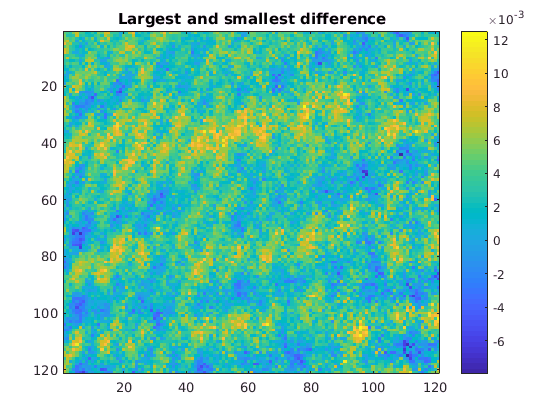

plot_title='Largest and smallest difference';
largest_minus_smallest=ODs_atom_region_size(:,:,kmax)-ODs_atom_region_size(:,:,1);
plot_image(largest_minus_smallest,plot_title);

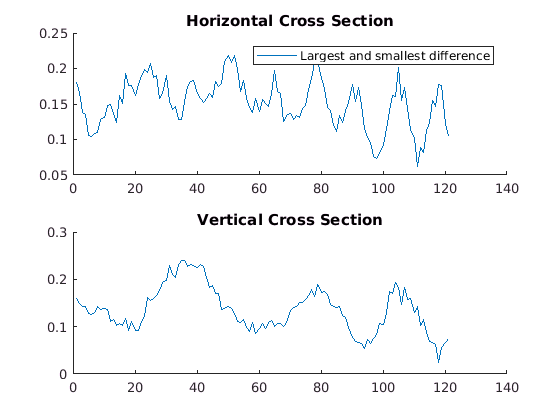

plot_cross_sections(largest_minus_smallest,plot_title,limits);

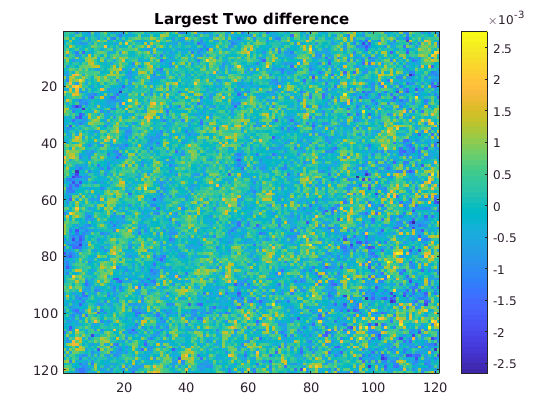

plot_title='Largest Two difference';
largest_minus_smallest=ODs_atom_region_size(:,:,kmax)-ODs_atom_region_size(:,:,kmax-1);
plot_image(largest_minus_smallest,plot_title);

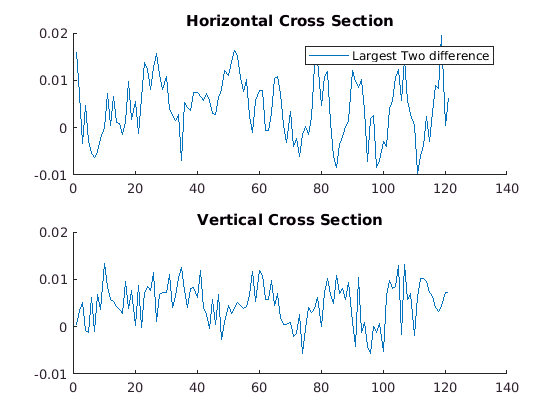

plot_cross_sections(largest_minus_smallest,plot_title,limits);

## Number of Basis Images

I usually use 20 basis images, since we usually dont' see much structure in basis images beyond that.  It's worth try to look at using different numbers of basis images though and compare the results.  Due to the nature of linear algebra projections, using more basis vectors will always decrease the residual signal in the image outside the atom region.  However, this doesn't necessarily mean that the reconstructed background in the atom region is improving; in fact using too many basis vectors may just start adding noise due to over-fitting.

A good way to do compare the results in a fair manner is to try reconstructing the background for a series of images with no atoms (while still ignoring the atom-free "atom region") and then looking at the noise in the atom region, which ideally would have OD=0 everywhere.  As a performance metric, we can take the variance of the image in that region and plot that as a function of number of basis vectors.

It turns out that the results are very insensitive to the number of basis vectors used as long as it is fairly reasonable.  Anywhere from 12 to 125 vectors or so gave variances within 1% of the optimal for this data set.  Therefore 20 basis vectors seems like a safe number.

disp('Reconstructing atom-free images to see how well we can reconstruct the background in atom region');

Reconstructing atom-free images to see how well we can reconstruct the background in atom region


image_in=zeros(121,121); %dummy image with correct dimensions
row_min=10; row_max=100; col_min=40; col_max=90;
back_region = make_back_region(image_in,row_min,row_max,col_min,col_max);
max_vectors = 300; %We'll get many basis vectors, and use subsets of them
atom_region=logical(1-back_region); %Used for logical indexing to select out atom region pixels

%First make the basis
ls_pattern = fullfile('20170406','*_back.ascii');
file_list = get_file_list(ls_pattern);
[basis_eig, mean_back] = make_basis_eig(file_list,back_region,max_vectors);

%Now we'll try using more and more of those basis vectors
n_basis_list=1:max_vectors;
variances=zeros(1,length(n_basis_list));
%Copy and pasted data so that 'NoAtoma1_*_raw (copy).ascii' matches first 20 shots of that sequence
series_name_pattern = fullfile('20170406','NoAtoma1_%d_raw.ascii');
atom_file_list=indices_to_file_list(series_name_pattern,1:20); %Only images 1->20 of that sequence
for k=1:length(n_basis_list)
    n_basis=n_basis_list(k);
    trimmed_basis_eig=basis_eig(:,1:n_basis); %Only use the n_basis most important eigenfaces
    OD_eig_no_atoms = process_list_eig(atom_file_list,trimmed_basis_eig,mean_back,back_region);
    atom_pixels=OD_eig_no_atoms(atom_region);
    variances(k)=var(atom_pixels(:));
end

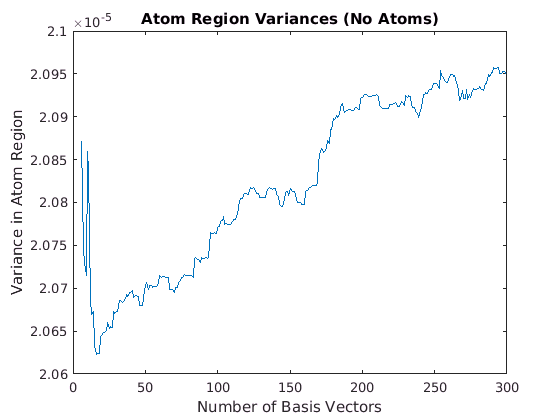

%Too much error for <~10 vectors makes it hard to see features in plot
min_index=6;
figure();
plot( n_basis_list(min_index:end), variances(min_index:end) );
title('Atom Region Variances (No Atoms)');
xlabel('Number of Basis Vectors');
ylabel('Variance in Atom Region');

## Systematic *_raw and *_back differences?

From the last few sections, it seems that the presence of fringes in our images even with eigenfaces processing is not from using the wrong size for the atom region or from using the wrong number of basis vectors.  At this point I'm starting to think that, for our system, the fringe patterns in the raw image may not be completely in the vector space spanned by the background images.  This is possible if, for example, the shutters systematically shake the camera so that the fringe pattern moves between the raw and back images.

If this is really an issue, a better solution may be to take the _back image sooner after the corresponding _raw image (currently they're taken about 500ms later).  If we quickly tune the laser off-resonance, we could even take the _back image before the atoms fly away.  This would give the fringe patterns less time to move between images.  However, before looking into that we should try to figure out a way to see if this is really the problem.

To test that there may be systematic differences between the raw and back images, let's take a look at data from a No-Atoms series.  Let's try to reconstruct the _raw images from that sequence from all the _back images from that day.  Then let's use the _raw from the No-Atom series and the _back from other shots only to reconstruct the _back from the No-Atom series.  If the fringes in the _raw images are just like the ones in the _back series, then both of those reconstructions should perform equally well.  If they are systematically different, then I'd expect the construction of the _back images to work better because they'll be closer to the _back images from other sequences, which are used when constructing both bases.

Turns out that the residuals from each case are almost identical.  This could mean simply that using the other _back images didn't help much, or it could mean that the images are not systematically different to any significant degree, so this test is null.

As mentioned above in this live script, using back images taken before and after the raw images makes the code perform better.  It's possible that by taking images over a long time, the temperature drifts shift the finges in the back images around so that we get enough variety to reconstruct raw images well.  This may explain why the fringes here are smaller and less aparent than in the Mathematica notebook on our analysis computer.  There we're always analyzing new data and therefore don't have _back images taken long after the _raw images.  I've just checked and for one sequence, the fringe amplitude decreased when I re-analyzed the data after  more shots were taken.  This may be the best way forward, although taking the _back image sooner after the _raw image may still help.

disp('Reconstructing background images for comparison');
image_in=zeros(121,121); %dummy image with correct dimensions
row_min=10; row_max=100; col_min=40; col_max=90;
back_region = make_back_region(image_in,row_min,row_max,col_min,col_max);
max_vectors = 20; %20 is typically a good number for this

Reconstructing background images for comparison


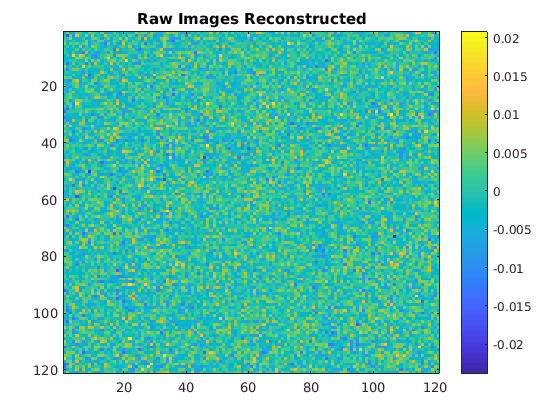


%Get lists of raw files from this series, back files from this series, and all other back_files
raw_file_list=indices_to_file_list( fullfile('20170406','NoAtoma1_%d_raw.ascii') ,1:20); %Raw images from this series
back_file_list=indices_to_file_list( fullfile('20170406','NoAtoma1_%d_back.ascii') ,1:20); %Back images from this series only
other_back_file_list = get_file_list( fullfile('20170406','*_back.ascii') );
other_back_file_list=setdiff(other_back_file_list,back_file_list); %Back images from other shots only
limits = [row_min,row_max,col_min,col_max]; %For integrating cross sections

%Now let's analyze the _raw images with all _back
file_list=vertcat(other_back_file_list,back_file_list);
[basis_eig, mean_back] = make_basis_eig(file_list,back_region,max_vectors);
OD_eig_raw = process_list_eig(raw_file_list,basis_eig,mean_back,back_region);
raw_label='Raw Images Reconstructed';
plot_image(OD_eig_raw,raw_label);
fig=plot_cross_sections(OD_eig_raw,raw_label,limits);

%Now let's analyze the _back images with the _raw images and the _back from the other shots
file_list=vertcat(other_back_file_list,raw_file_list);

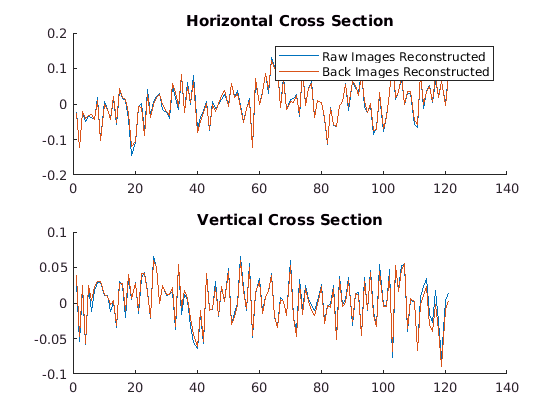

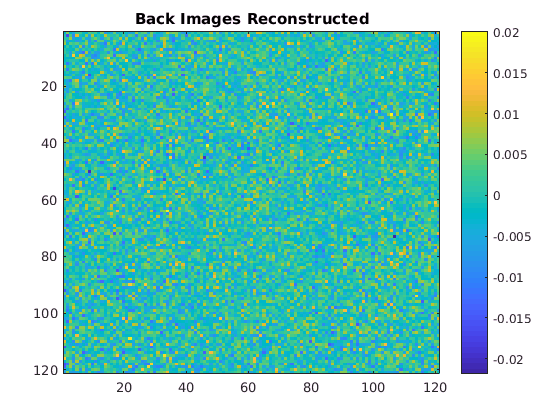

[basis_eig, mean_back] = make_basis_eig(file_list,back_region,max_vectors);
OD_eig_back = process_list_eig(raw_file_list,basis_eig,mean_back,back_region);
back_label='Back Images Reconstructed';
plot_image(OD_eig_back,back_label);
plot_cross_sections(OD_eig_back,back_label,limits,fig);